clc
clearvars

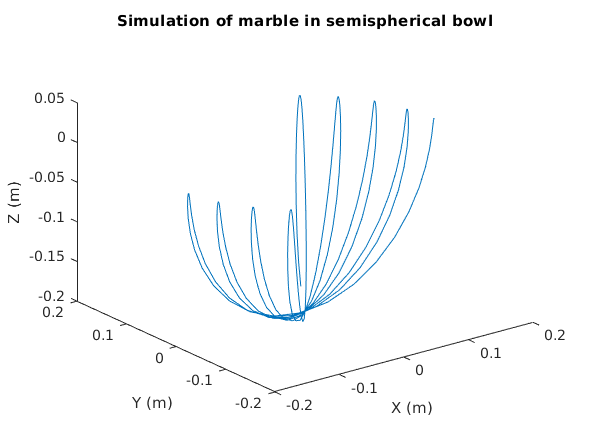

% initial position
r = 0.2;     % m
theta0 = 0;
phi0 = pi/2;

% initial velocity
d_theta = 0.1;   % m/s
d_phi = 0;

% pack initial conditions into column vector
init = [theta0 d_theta phi0 d_phi]';

[t,p] = simulate_marble(init);

theta = p(:,1);
phi = p(:,3);

x = r.*sin(phi).*cos(theta);
y = r.*sin(phi).*sin(theta);
z = r.*cos(phi);

figure
plot3(x,y,z)
title("Simulation of marble in semispherical bowl")
xlabel("X (m)")
ylabel("Y (m)")
zlabel('Z (m)')

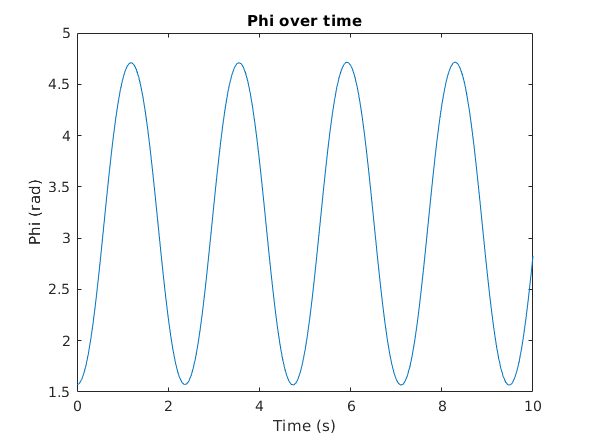


figure
plot(t,phi)
title("Phi over time")
xlabel("Time (s)")
ylabel("Phi (rad)")

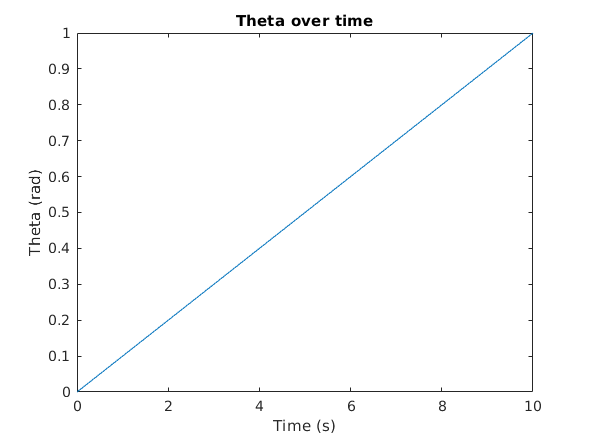


figure
plot(t,theta)
title("Theta over time")
xlabel("Time (s)")
ylabel("Theta (rad)")

function [t,p] = simulate_marble(init)
    % time span
    tspan = [0:.05:10];
    
    % simulation params
    g = 9.8;    % m/s^2
    
    [t,p] = ode45(@f,tspan,init);
    
    function dpdt = f(~,p)
        % governing ode equations
        d_theta = p(2);
        dd_theta = 0;
        d_phi = p(4);
        dd_phi = g*sin(p(3));
        
        % pack ode into column vector
        dpdt = [d_theta dd_theta d_phi dd_phi]';
    end
    
end